% datatable81 = unnamed;

Import data table and convert to array

load datatable.mat
data = table2array(datatable);

% p = data(:,1:4)';
% t = data(:,5:6)';
% 
% p1 = p(1,:);
% p2 = p(2,:);
% p3 = p(3,:);
% p4 = p(4,:);
% 
% t1 = t(1,:);
% t2 = t(2,:);
% 
% p1n = (data(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
% p2n = (data(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
% p3n = (data(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
% p4n = (data(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));
% t1n = (data(:,5)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));
% t2n = (data(:,6)-min(data(:,6)))./(max(data(:,6))-min(data(:,6)));
% 
% pn = [p1n p2n p3n p4n]';
% tn = [t1n t2n]';

%manual mapminmax for multi-target output
%[ttnn,ttss] = mapminmax(t)
%mapminmax('reverse',ttnn,ttss)

## hyperparameter optimization (number of neurons)

load datatable.mat
data = datatable144;
numdata = numel(data(:,1))

numdata = 144

foldsize = ceil(numdata/5);

%% randomize
randata = data(randperm(size(data,1)),:)

randata = 	1.0e+03 *

    0.0020    0.1200    0.4000    0.0035    0.0654    1.9759
    0.0030    0.1400    0.3000    0.0050    0.0495    1.3254
    0.0030    0.1400    0.4000    0.0020    0.0528    0.9810
    0.0015    0.1000    0.5000    0.0035    0.0703    1.4454
    0.0015    0.1000    0.4000    0.0020    0.0717    0.8827
    0.0015    0.1600    0.5000    0.0020    0.1109    1.0069
    0.0020    0.1000    0.5000    0.0050    0.0546    1.8413
    0.0020    0.1200    0.3000    0.0020    0.0659    0.8954
    0.0030    0.1000    0.4000    0.0020    0.0374    1.0541
    0.0015    0.1600    0.3000    0.0050    0.1104    1.4015


%% normalize
normdata = normalize(randata,"range");

fold1 = normdata(1:foldsize,:);
fold2 = normdata(foldsize+1:2*foldsize,:);
fold3 = normdata(2*foldsize+1:3*foldsize,:);
fold4 = normdata(3*foldsize+1:4*foldsize,:);
fold5 = normdata(4*foldsize+1:numdata,:);

f1 = [fold1;fold2;fold3;fold4;fold5]';
f2 = [fold2;fold1;fold3;fold4;fold5]';
f3 = [fold3;fold1;fold2;fold4;fold5]';
f4 = [fold4;fold1;fold2;fold3;fold5]';
f5 = [fold5;fold1;fold2;fold3;fold4]';

valInd = 1:foldsize;
trainInd = foldsize+1:numdata;

for i=1:50
Fcn = 'logsig';
netf1 = fitnet(i,'trainlm');
netf2 = fitnet(i,'trainlm');
netf3 = fitnet(i,'trainlm');
netf4 = fitnet(i,'trainlm');
netf5 = fitnet(i,'trainlm');

netf1.divideFcn = 'divideind';
netf1.divideParam.valInd = 1:foldsize;
netf1.divideParam.trainInd = foldsize+1:numdata;
netf1.inputs{1}.processFcns   = {'removeconstantrows'};
netf1.outputs{2}.processFcns  = {'removeconstantrows'};
netf1.layers{1}.transferFcn = Fcn;

netf2.divideFcn = 'divideind';
netf2.divideParam.valInd = 1:foldsize;
netf2.divideParam.trainInd = foldsize+1:numdata;
netf2.inputs{1}.processFcns   = {'removeconstantrows'};
netf2.outputs{2}.processFcns  = {'removeconstantrows'};
netf2.layers{1}.transferFcn = Fcn;

netf3.divideFcn = 'divideind';
netf3.divideParam.valInd = 1:foldsize;
netf3.divideParam.trainInd = foldsize+1:numdata;
netf3.inputs{1}.processFcns   = {'removeconstantrows'};
netf3.outputs{2}.processFcns  = {'removeconstantrows'};
netf3.layers{1}.transferFcn = Fcn;

netf4.divideFcn = 'divideind';
netf4.divideParam.valInd = 1:foldsize;
netf4.divideParam.trainInd = foldsize+1:numdata;
netf4.inputs{1}.processFcns   = {'removeconstantrows'};
netf4.outputs{2}.processFcns  = {'removeconstantrows'};
netf4.layers{1}.transferFcn = Fcn;

netf5.divideFcn = 'divideind';
netf5.divideParam.valInd = 1:foldsize;
netf5.divideParam.trainInd = foldsize+1:numdata;
netf5.inputs{1}.processFcns   = {'removeconstantrows'};
netf5.outputs{2}.processFcns  = {'removeconstantrows'};
netf5.layers{1}.transferFcn = Fcn;

[netf1,trf1] = train(netf1,f1(1:4,:),f1(5:6,:));
[netf2,trf2] = train(netf2,f2(1:4,:),f2(5:6,:));
[netf3,trf3] = train(netf3,f3(1:4,:),f3(5:6,:));
[netf4,trf4] = train(netf4,f4(1:4,:),f4(5:6,:));
[netf5,trf5] = train(netf5,f5(1:4,:),f5(5:6,:));
err(i) =(trf1.best_vperf+trf2.best_vperf+trf3.best_vperf+trf4.best_vperf+trf5.best_vperf)/5;
end

plot(err);
[M0,I0] = min(err);
disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    14



disp('Which has MSE =')

Which has MSE =


disp(M0)

    0.0014



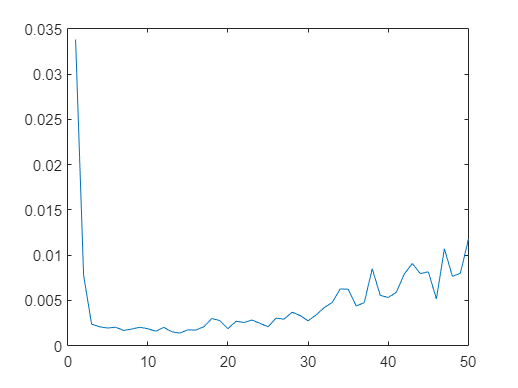

hold off;

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net0.inputs{1}.processFcns   = {'removeconstantrows'};
net0.outputs{2}.processFcns  = {'removeconstantrows'};
net0.layers{1}.transferFcn = 'poslin';

[net0,tr0] = train(net0,pn,tn);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input


plot(mse_val0,'-');

disp('training index of best MSE value set is')
disp(I0)
disp('Which has MSE =')
disp(M0)
hold off;

net1 = fitnet(12,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 12
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inpu

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net1.inputs{1}.processFcns   = {'removeconstantrows'};
net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'logsig';

[net1,tr1] = train(net1,f1(1:4,:),f1(5:6,:));

input = normalize(datatable144(:,1:4),'range');
output_ANN1 = net1(input')

output_ANN1 =     0.4912    0.4895    0.4896    0.5022    0.5016    0.5038    0.5083    0.5078    0.5102    0.6352    0.6357    0.6371    0.6495    0.6461    0.6462    0.6560    0.6540    0.6564    0.8025    0.8046    0.8080    0.8120    0.8087    0.8091    0.8218    0.8185    0.8196    0.9850    0.9873    0.9906    0.9883    0.9868    0.9879    0.9978    0.9934    0.9913    0.2745    0.2721    0.2716    0.2765    0.2762    0.2783    0.2749    0.2743    0.2761    0.3593    0.3586    0.3593    0.3663    0.3648
    0.0400    0.4207    0.6655    0.1092    0.3992    0.7480    0.1068    0.4080    0.7636    0.0368    0.4796    0.6207    0.0671    0.4138    0.6943    0.0827    0.4126    0.7390    0.0210    0.5598    0.5604    0.0256    0.4128    0.6096    0.0932    0.3858    0.6797    0.0443    0.6211    0.4843    0.0524    0.4165    0.5110    0.1332    0.3295    0.5784    0.0324    0.5588    0.6049    0.0909    0.4471    0.6833    0.1049    0.4065    0.7164    0.0245    0.5917    0.5252    0

ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =    99.0517   98.8370   98.8444  100.4405  100.3639  100.6341  101.2039  101.1412  101.4400  117.2027  117.2685  117.4413  119.0043  118.5814  118.5958  119.8310  119.5797  119.8787  138.3071  138.5662  138.9981  139.5058  139.0826  139.1363  140.7409  140.3228  140.4612  161.3221  161.6091  162.0263  161.7360  161.5447  161.6799  162.9265  162.3780  162.1162   71.7245   71.4257   71.3565   71.9742   71.9392   72.2088   71.7793   71.6936   71.9250   82.4128   82.3246   82.4159   83.2958   83.1123


ANNSEA = ((output_ANN1(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

ANNSEA = 	1.0e+03 *

    0.7978    1.4471    1.8646    0.9159    1.4104    2.0054    0.9118    1.4254    2.0320    0.7923    1.5476    1.7882    0.8441    1.4354    1.9138    0.8707    1.4334    1.9900    0.7654    1.6844    1.6853    0.7733    1.4337    1.7692    0.8886    1.3875    1.8888    0.8051    1.7888    1.5556    0.8190    1.4400    1.6011    0.9568    1.2916    1.7160    0.7849    1.6827    1.7613    0.8846    1.4921    1.8950    0.9084    1.4230    1.9514    0.7714    1.7388    1.6254    0.8973    1.5962


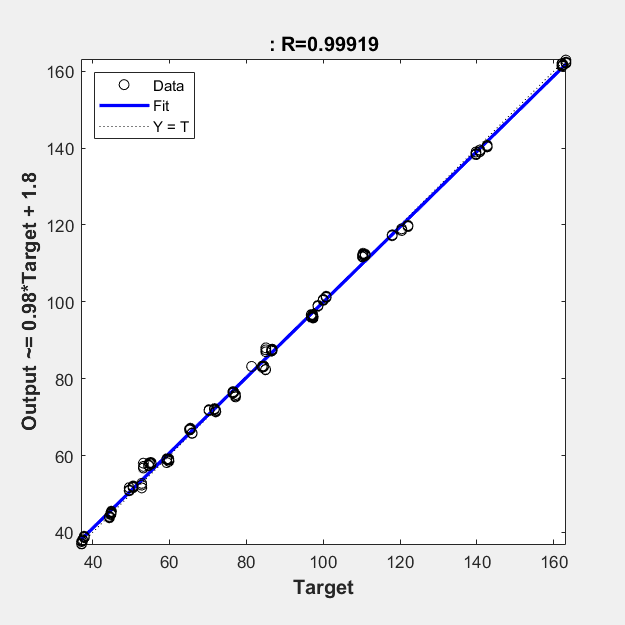

plotregression(datatable144(:,5),ANNIPF');

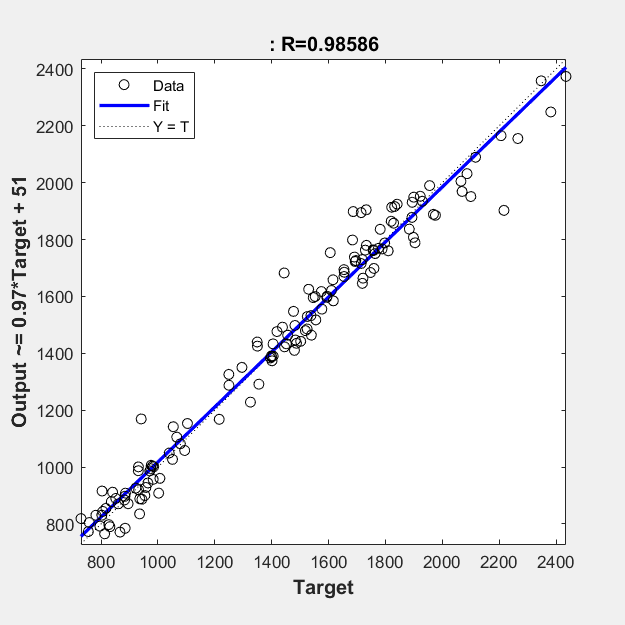

plotregression(datatable144(:,6),ANNSEA');

% plotregression(t1n,output_ANN1(1,:));
% plotregression(t2n,output_ANN1(2,:));


pred = net1([0.75 0.75 0.75 0.75]')

pred =     0.1913
    0.5784



IPF = ((pred(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

IPF = 62.5039

SEA = ((pred(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

SEA = 1.7162e+03


maxipf=max(data(:,5))

maxipf = 169.8391

minipf=min(data(:,5))

minipf = 37.1100

maxsea=max(data(:,6))

maxsea = 2.4352e+03

minsea=min(data(:,6))

minsea = 729.5885

## ANN function test unit

data = datatable144;
testing(:,1) = (testingdata(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
testing(:,2) = (testingdata(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
testing(:,3) = (testingdata(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
testing(:,4) = (testingdata(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));

x = testing;
%x = normalize(data(:,1:4),"range");
output_ANN1 = tansig144(x');
ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =   128.8777  118.5434  123.5302   99.5621   86.4999   78.8171   83.1685   92.7913   83.1757   72.7302


ANNSEA = ((output_ANN1(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

ANNSEA = 	1.0e+03 *

    1.6893    1.7186    1.6413    1.7764    1.1579    1.8821    1.5210    1.8466    1.9359    1.6151



plotregression(testing(:,5),ANNIPF');
plotregression(testing(:,6),ANNSEA');

%     compet - Competitive transfer function.
%     elliotsig - Elliot sigmoid transfer function.
%     hardlim - Positive hard limit transfer function.
%     hardlims - Symmetric hard limit transfer function.
%     logsig - Logarithmic sigmoid transfer function.
%     netinv - Inverse transfer function.
%     poslin - Positive linear transfer function.
%     purelin - Linear transfer function.
%     radbas - Radial basis transfer function.
%     radbasn - Radial basis normalized transfer function.
%     satlin - Positive saturating linear transfer function.
%     satlins - Symmetric saturating linear transfer function.
%     softmax - Soft max transfer function.
%     tansig - Symmetric sigmoid transfer function.
%     tribas - Triangular basis transfer function.

Y = poslin144(R);